x = 1:10;
y = x.^2;
kernel = [1, -1];

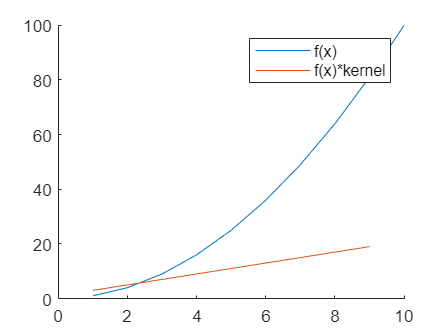

y_conv = conv(y,kernel,"same");
hold on
plot(x, y, x(1:end-1), y_conv(1:end-1))
legend(["f(x)", "f(x)*kernel"])
hold off

x = 1:12;
y2 = triang(200*.06)

y2 =     0.0833
    0.2500
    0.4167
    0.5833
    0.7500
    0.9167
    0.9167
    0.7500
    0.5833
    0.4167


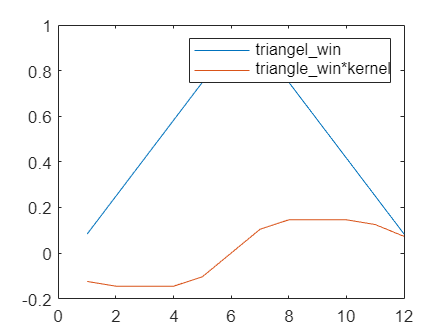

kernel2 = [-2,-1,1,2]/8;
y_conv2 = conv(y2, kernel2, "same");
plot(x, y2, x, y_conv2)
legend(["triangel\_win", "triangle\_win*kernel"])